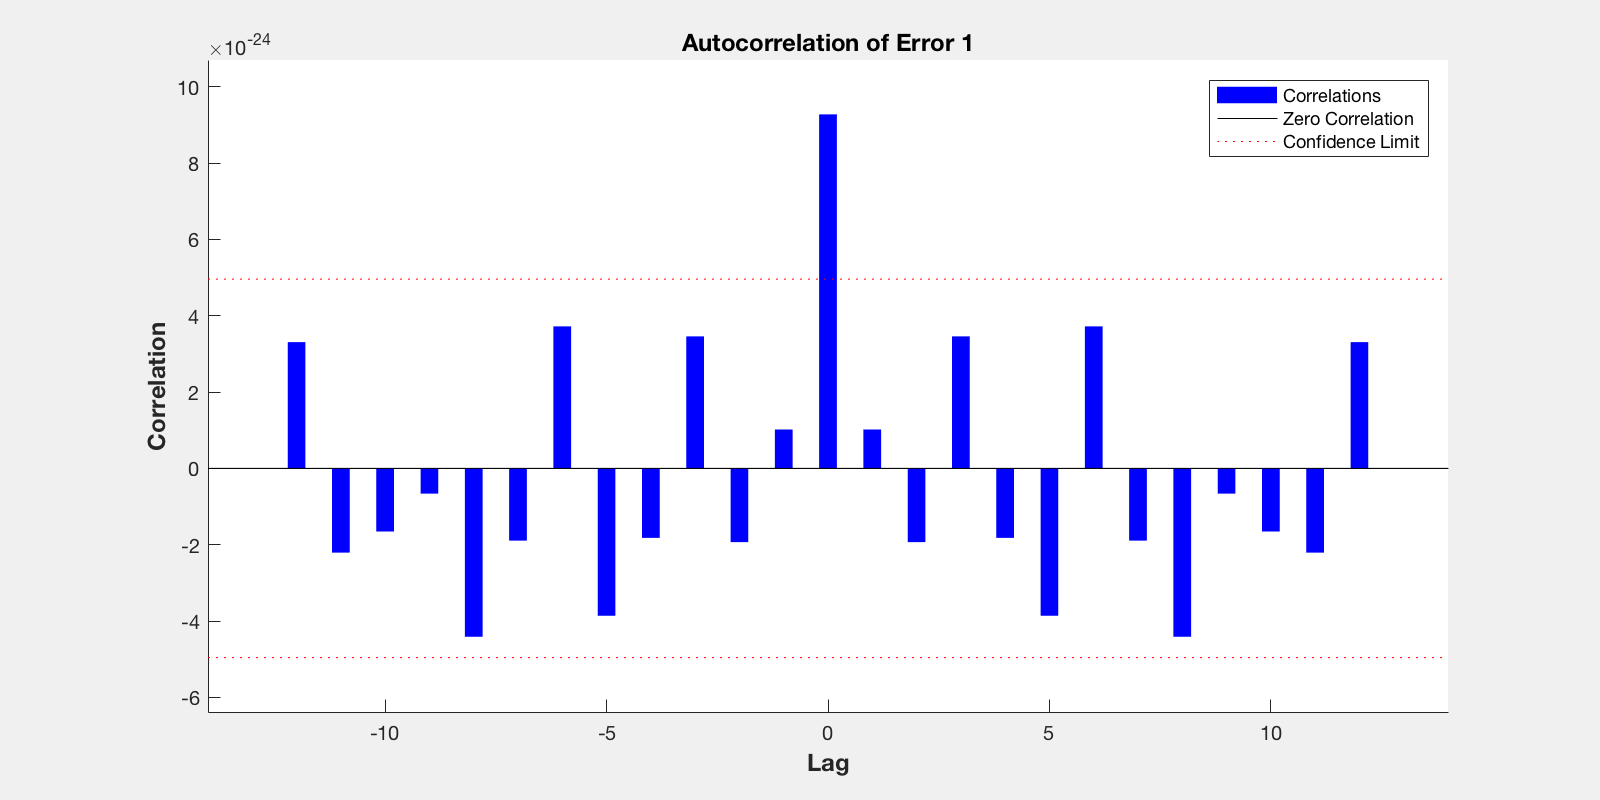

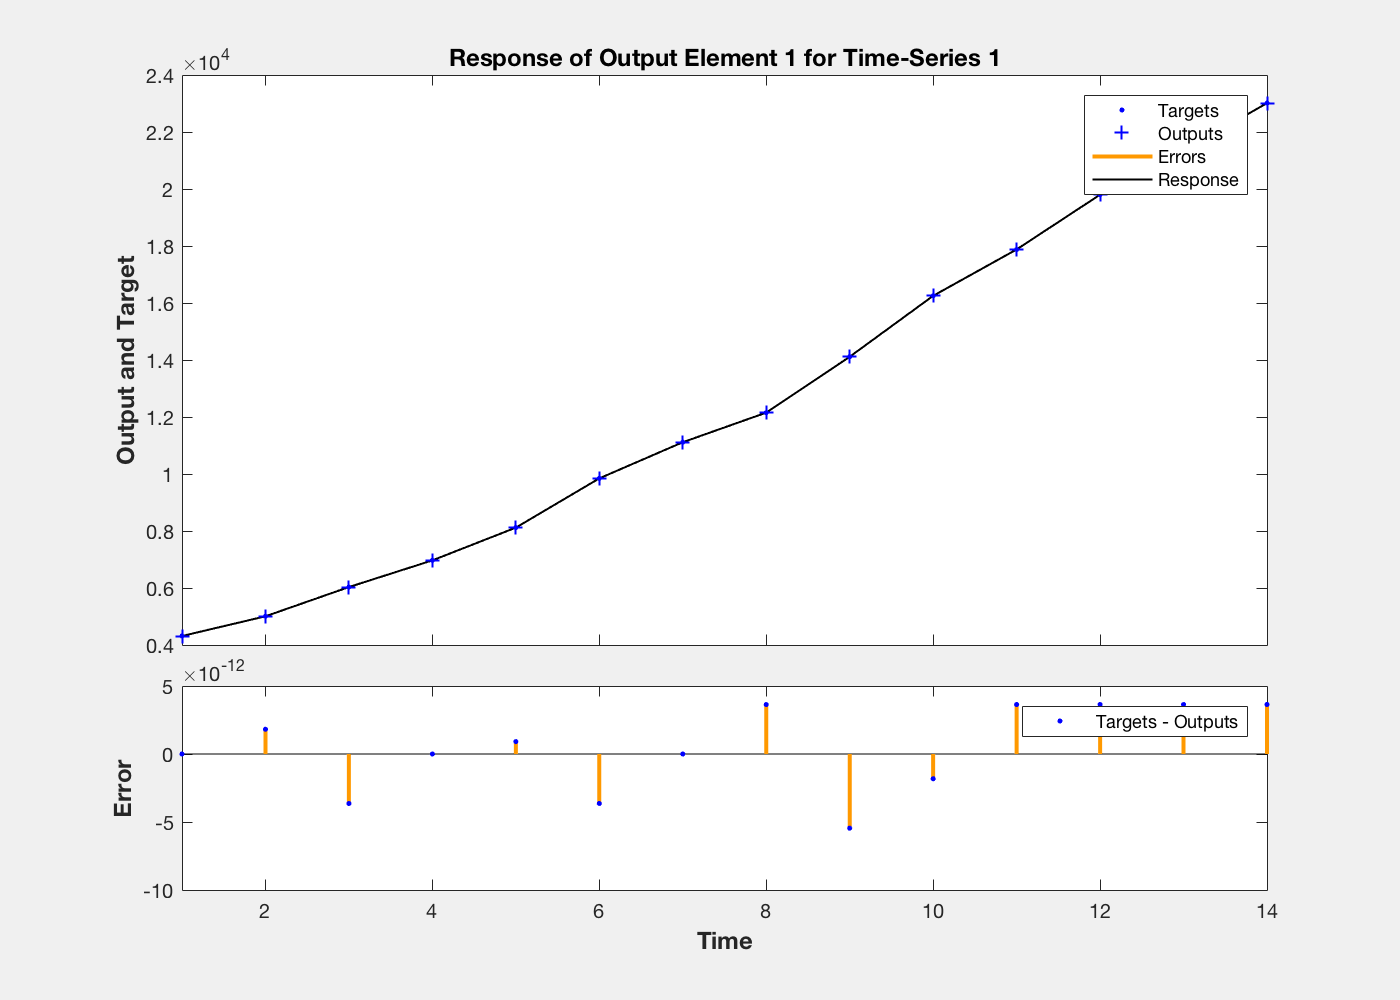

data = xlsread('data.xlsx','Sheet1','C2:T32');
trainData = data(:, 18:-1:2);
testData = data(:, 1);
inputTrain = [trainData testData];
%narnetP(trainData(1,:)',4);

% outputTrain = trainData(:, 1);


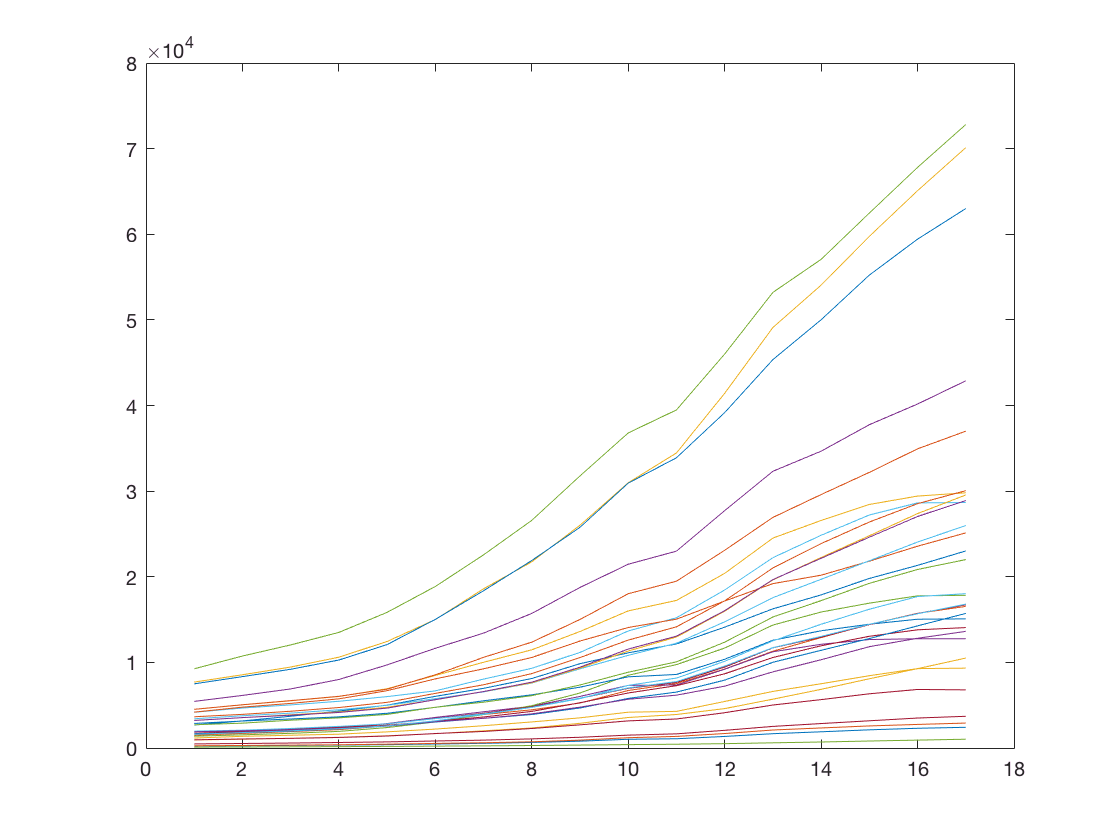

plot(inputTrain');

[input, inputOpt] = mapminmax(inputTrain);
[output, outputOpt] = mapminmax(outputTrain');


inputCell = num2cell(input(1,2:17));
outputCell = num2cell(input(1,1));
[net, tr, perf,e ] = narnatPredict(inputCell,outputCell,3,10);

perf = 0.0015

mse =mapminmax('reverse',e,inputOpt)

mse =    1.0e+04 *

    2.6798
    1.9286
    3.4162
    1.3891
    2.0107
    3.0763
    1.6016
    1.6456
    2.9456
    8.1931


fout=net(num2cell(output(1,1)));

net = newff(input, output, 20);
net.trainParam.epochs = 100;
net.trainParam.lr = 0.1;
net.trainParam.goal = 0.00004;
net = train(net, input, output);

Error using network/train (line 340)
Inputs and targets have different numbers of samples.

T = simplenar_dataset;
plot(cell2mat(T));
net = narnet(1:3,10);
[Xs,Xi,Ai,Ts] = preparets(net,{},{},T);
net = train(net,Xs,Ts,Xi,Ai);
view(net)
Y = net(Xs,Xi);
perf = perform(net,Ts,Y)